Combine 3D image segments into a single image

The zip file contains the original data split into 10x10 blocks of 200x200x~300. The file name gives the coordinates of each block for when you rebuild

source_dir = '~/p51_higher_fidelity_segmentation/P51new';
placenta = [];
for j1=1:200:1801
%for j1=1:2 00:801 %half of the placenta for now
  rowSection = [];  
  for j2 = 1:200:1801
      filename = fullfile(source_dir,['stack_',num2str(j1),'_',num2str(j2),'_new.nii.gz']);
      segment = load_nii(filename);    
      rowSection = [rowSection,segment.img];
  end
  placenta=[placenta;rowSection];
end

write tiff slices from nii

tiff_dir = '~/p51_higher_fidelity_segmentation/tiff';
for i=1:306 
  slice = placenta(:,:,i:i); 
  filename = fullfile(tiff_dir,['P51_hf_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

read high fidelity tiff slices

tiff_dir = '~/p51_higher_fidelity_segmentation/tiff';
placenta = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_hf_slice_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta(:,:,i) = slice;
end

volumeViewer(placenta);

Remove non vessel placental tissue

vessels = placenta;
vessels(vessels < 105) = 0; %remove values less than 105
%remove voxels on the plate- these are not vessels
vessels(1:35,:,:) = 0; %(y,x,z)
vessels(1700:2000,:,:) = 0

no_vessel_voxels = length(find(vessels));
placenta_vascular_density = (no_vessel_voxels/no_placenta_voxels)*100

placenta_vascular_density = 7.1130

Write out a point cloud text file of the vessel surface

source_dir = '~/p51_higher_fidelity_segmentation/isosurfaces';
vessels_copy = vessels;
vessels_copy(vessels_copy >= 105)=1;
vessels_surface = isosurface(vessels_copy,0);
filename = fullfile(source_dir,'vessels_surface.txt');
dlmwrite(filename,vessels_surface.vertices,'delimiter','\t');

small_vessels = vessels;
%this area is mostly occupied by large vessels that have already been skeletonised
small_vessels(275:1500,275:1500,1:100) = 0; 
small_vessels(500:1200,500:1200,1:150) = 0; %removed additional section in the middle occupied by large vessels 

clearvars -except small_vessels;

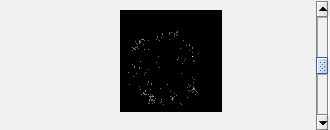

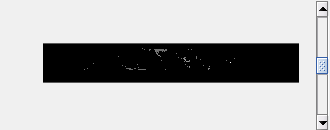

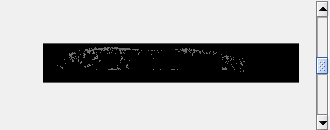

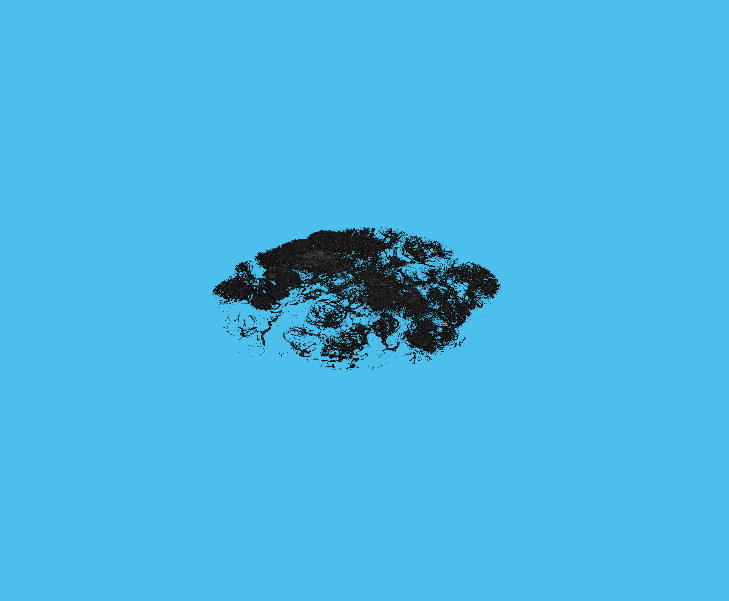

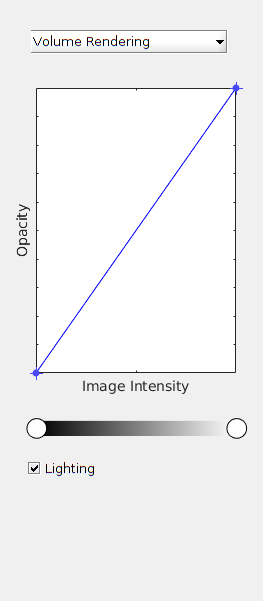

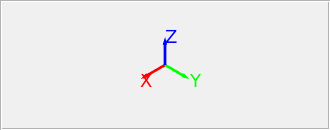

volumeViewer(small_vessels);

write tiff slices of small vessels (with some large vessels)

tiff_dir = '~/p51_higher_fidelity_segmentation/small_vessel_tiff';
for i=1:306 
  slice = small_vessels(:,:,i:i); 
  filename = fullfile(tiff_dir,['P51_sv_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

read small vessel tiff slices (with some large vessels)

tiff_dir = '~/p51_higher_fidelity_segmentation/small_vessel_tiff';
slice = [];
small_vessels2 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_sv_slice_',num2str(i),'.tiff']);
    slice = imread(filename);
    small_vessels2(:,:,i) = slice;
end

%populate array with large vessels
%remove large vessels from small vessels using the lower fideliy segmented images
%(get the placenta array using process_images)
large_vessel_inds = find(placenta == 3);
small_vessels(large_vessel_inds) = 0;

write tiff slices of small vessels (newer version with more large vessel segments removed)

tiff_dir = '~/p51_higher_fidelity_segmentation/sv_tiff_lv_removed';
slice = [];
for i=1:306 
  slice = small_vessels2(:,:,i:i); 
  filename = fullfile(tiff_dir,['P51_sv_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

read small vessel tiff slices

tiff_dir = '~/p51_higher_fidelity_segmentation/sv_tiff_lv_removed';
slice = [];
small_vessels2 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_sv_slice_',num2str(i),'.tiff']);
    slice = imread(filename);
    small_vessels2(:,:,i) = slice;
end


read tiff slices of placenta seed points (every 5 units)

tiff_dir = '~/placenta_patient_51/seed_points_every_5_units';
slice = [];
placenta_points_5 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_5(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 8 units)

tiff_dir = '~/placenta_patient_51/seed_points_every_8_units';
slice = [];
placenta_points_8 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_8(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 10 units)

tiff_dir = '~/placenta_patient_51/seed_points_every_10_units';
slice = [];
placenta_points_10 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_seed_points_10_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_10(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 15 units)

tiff_dir = '~/placenta_patient_51/seed_points_every_15_units';
slice = [];
placenta_points_15 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_15(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 20 units)

tiff_dir = '~/placenta_patient_51/seed_points_every_20_units';
slice = [];
placenta_points_20 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_20(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 23 units)

tiff_dir = '~/placenta_patient_51/seed_points_every_23_units';
slice = [];
placenta_points_23 = zeros(2000,2000,306);
for i=1:306
    filename = fullfile(tiff_dir,['P51_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_23(:,:,i) = slice;
end

get vascular density per cube (fraction of vessel voxels per 25x25x25 cube)

vascular_density = zeros(1,91728); %array shape needs to be updated if cube_edge_length is changed
i_density = 1;
cube_edge_length = 24;
no_of_cubes = 0;
for y=1:cube_edge_length:2000
  for x=1:cube_edge_length:2000
      for z=1:cube_edge_length:306
          no_of_cubes = no_of_cubes + 1;
          calc_no_voxels = 0;
          y_start = y;
          y_end = y + cube_edge_length;
          if y_end > 2000
              y_end = 2000;
              calc_no_voxels = 1;
          end
          x_start = x;
          x_end = x + cube_edge_length;
          if x_end > 2000
              x_end = 2000;
              calc_no_voxels = 1;
          end
          z_start = z;
          z_end = z + cube_edge_length;
          if z_end > 306
              z_end = 306;
              calc_no_voxels = 1;
          end
          if calc_no_voxels
              no_of_voxels = (y_end - y_start + 1)*(x_end - x_start + 1)*(z_end - z_start + 1); 
          else
              no_of_voxels = (cube_edge_length+1)^3;
          end  
          cube = small_vessels2(y_start:y_end,x_start:x_end,z_start:z_end);
          small_vessel_voxels = find(cube);
          if ~isempty(small_vessel_voxels)
             vascular_density(i_density) = length(small_vessel_voxels)/no_of_voxels; 
          else
             vascular_density(i_density) = 0; 
          end
          i_density = i_density + 1;
      end
  end
end
 

91728 cubes in total

82% of them have 0 vascular density (75274) 

plot vascular density values > 0

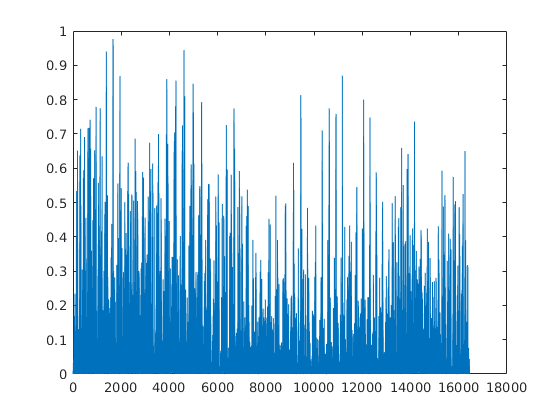

ans = 16454


density_over_zero = vascular_density(find(vascular_density));
histogram(density_over_zero);

populate seed points depending on vascular density (fraction of vessel voxels per 24x24x24 cube)

need to do this separately for each seed density due to memory issues

load small_vessels2 and placenta_points20 before running this section

placenta_points = zeros(2000,2000,306);
cube_edge_length = 24;
vascular_density = 0;
for y=1:cube_edge_length:2000
  for x=1:cube_edge_length:2000
      for z=1:cube_edge_length:306
          calc_no_voxels = 0;
          y_start = y;
          y_end = y + cube_edge_length;
          if y_end > 2000
              y_end = 2000;
              calc_no_voxels = 1;
          end
          x_start = x;
          x_end = x + cube_edge_length;
          if x_end > 2000
              x_end = 2000;
              calc_no_voxels = 1;
          end
          z_start = z;
          z_end = z + cube_edge_length;
          if z_end > 306
              z_end = 306;
              calc_no_voxels = 1;
          end
          if calc_no_voxels
              no_of_voxels = (y_end - y_start + 1)*(x_end - x_start + 1)*(z_end - z_start + 1); 
          else
              no_of_voxels = (cube_edge_length+1)^3;
          end  
          cube = small_vessels2(y_start:y_end,x_start:x_end,z_start:z_end);
          small_vessel_voxels = find(cube);
          temp_points = [];
          if ~isempty(small_vessel_voxels)
             vascular_density = length(small_vessel_voxels)/no_of_voxels; 
             if (vascular_density > 0) && (vascular_density <= 0.33)
                 placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = placenta_points_20(y_start:y_end,x_start:x_end,z_start:z_end);
             end      
          else
             %vascular density is 0
             placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = zeros(y_end - y_start + 1,x_end - x_start + 1,z_end - z_start + 1);
          end
      end
  end
end

clear placenta_points_20;
%load placenta_points_15

cube_edge_length = 24;
vascular_density = 0;
for y=1:cube_edge_length:2000
  for x=1:cube_edge_length:2000
      for z=1:cube_edge_length:306
          calc_no_voxels = 0;
          y_start = y;
          y_end = y + cube_edge_length;
          if y_end > 2000
              y_end = 2000;
              calc_no_voxels = 1;
          end
          x_start = x;
          x_end = x + cube_edge_length;
          if x_end > 2000
              x_end = 2000;
              calc_no_voxels = 1;
          end
          z_start = z;
          z_end = z + cube_edge_length;
          if z_end > 306
              z_end = 306;
              calc_no_voxels = 1;
          end
          if calc_no_voxels
              no_of_voxels = (y_end - y_start + 1)*(x_end - x_start + 1)*(z_end - z_start + 1); 
          else
              no_of_voxels = (cube_edge_length+1)^3;
          end  
          cube = small_vessels2(y_start:y_end,x_start:x_end,z_start:z_end);
          small_vessel_voxels = find(cube);
          temp_points = [];
          if ~isempty(small_vessel_voxels)
             vascular_density = length(small_vessel_voxels)/no_of_voxels; 
             if (vascular_density > 0.33) && (vascular_density <= 0.66)
                 placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = placenta_points_15(y_start:y_end,x_start:x_end,z_start:z_end);
             end      
          end
      end
  end
end

clear placenta_points_15;
%load placenta_points_10 8

cube_edge_length = 24;
vascular_density = 0;
for y=1:cube_edge_length:2000
  for x=1:cube_edge_length:2000
      for z=1:cube_edge_length:306
          calc_no_voxels = 0;
          y_start = y;
          y_end = y + cube_edge_length;
          if y_end > 2000
              y_end = 2000;
              calc_no_voxels = 1;
          end
          x_start = x;
          x_end = x + cube_edge_length;
          if x_end > 2000
              x_end = 2000;
              calc_no_voxels = 1;
          end
          z_start = z;
          z_end = z + cube_edge_length;
          if z_end > 306
              z_end = 306;
              calc_no_voxels = 1;
          end
          if calc_no_voxels
              no_of_voxels = (y_end - y_start + 1)*(x_end - x_start + 1)*(z_end - z_start + 1); 
          else
              no_of_voxels = (cube_edge_length+1)^3;
          end  
          cube = small_vessels2(y_start:y_end,x_start:x_end,z_start:z_end);
          small_vessel_voxels = find(cube);
          temp_points = [];
          if ~isempty(small_vessel_voxels)
             vascular_density = length(small_vessel_voxels)/no_of_voxels; 
             if (vascular_density > 0.66) && (vascular_density <= 1)
                 placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = placenta_points_8(y_start:y_end,x_start:x_end,z_start:z_end);
             end      
          end
      end
  end
end

clearvars -except placenta_points;
%save placenta_points to a text file (in process_images)

distribute vessel seed points evenly within the section of the placenta where smaller vessels are found

populate placenta_points_x and placenta (process_images.mlx)

large_vessel_inds = find(placenta == 3);
clear placenta;
placenta_points = placenta_points_23;
placenta_points(275:1500,275:1500,1:100) = 0;
placenta_points(500:1200,500:1200,1:150) = 0;
clear placenta_points_23;
placenta_points(large_vessel_inds) = 0;